clc
clear all
close all
%warning OFF

sys_cont=zpk([+1.6 +3.4],[-4/0.7 -1.6/3 +1.1],0.1)

sys_cont =
 
      0.1 (s-1.6) (s-3.4)
  ----------------------------
  (s+5.714) (s-1.1) (s+0.5333)
 
Continuous-time zero/pole/gain model.




BW=bandwidth(sys_cont);
Discret_ratio=30; % >2   % to signal can be reconstructable we must have 2*Bandwich
T_s=2*pi/(BW*Discret_ratio)

T_s = 0.4272


sys_discret=c2d(sys_cont,T_s,'zoh')

sys_discret =
 
  -0.0020776 (z-1.931) (z+8.362)
  ------------------------------
  (z-0.7963) (z-1.6) (z-0.08708)
 
Sample time: 0.42716 seconds
Discrete-time zero/pole/gain model.



[num_discret,den_discret]=tfdata(sys_discret);
num_discret=cell2mat(num_discret);
num_discret=num_discret(2:end)      ;B=num_discret

B =    -0.0021   -0.0134    0.0335


roots(num_discret)

ans =    -8.3623
    1.9307


den_discret=cell2mat(den_discret)   ;A=den_discret

A =     1.0000   -2.4831    1.4825   -0.1109



B(B==0) = [] ; % remove zeros

% Tf = 100 ;
% t = 0:Ts:Tf ;
tfinal=2000;
t = 0:T_s:tfinal;

#### General Input+white Noise

uc =(gensig('square' , tfinal/10 , tfinal ,T_s))';
% desire system
Am=poly([0.4 0.5 0.6])

Am =     1.0000   -1.5000    0.7400   -0.1200


Bm=(sum(Am)/sum(B))*B;
sys_ref=tf(Bm,Am,T_s)

sys_ref =
 
  -0.01377 z^2 - 0.08858 z + 0.2223
  ---------------------------------
    z^3 - 1.5 z^2 + 0.74 z - 0.12
 
Sample time: 0.42716 seconds
Discrete-time transfer function.



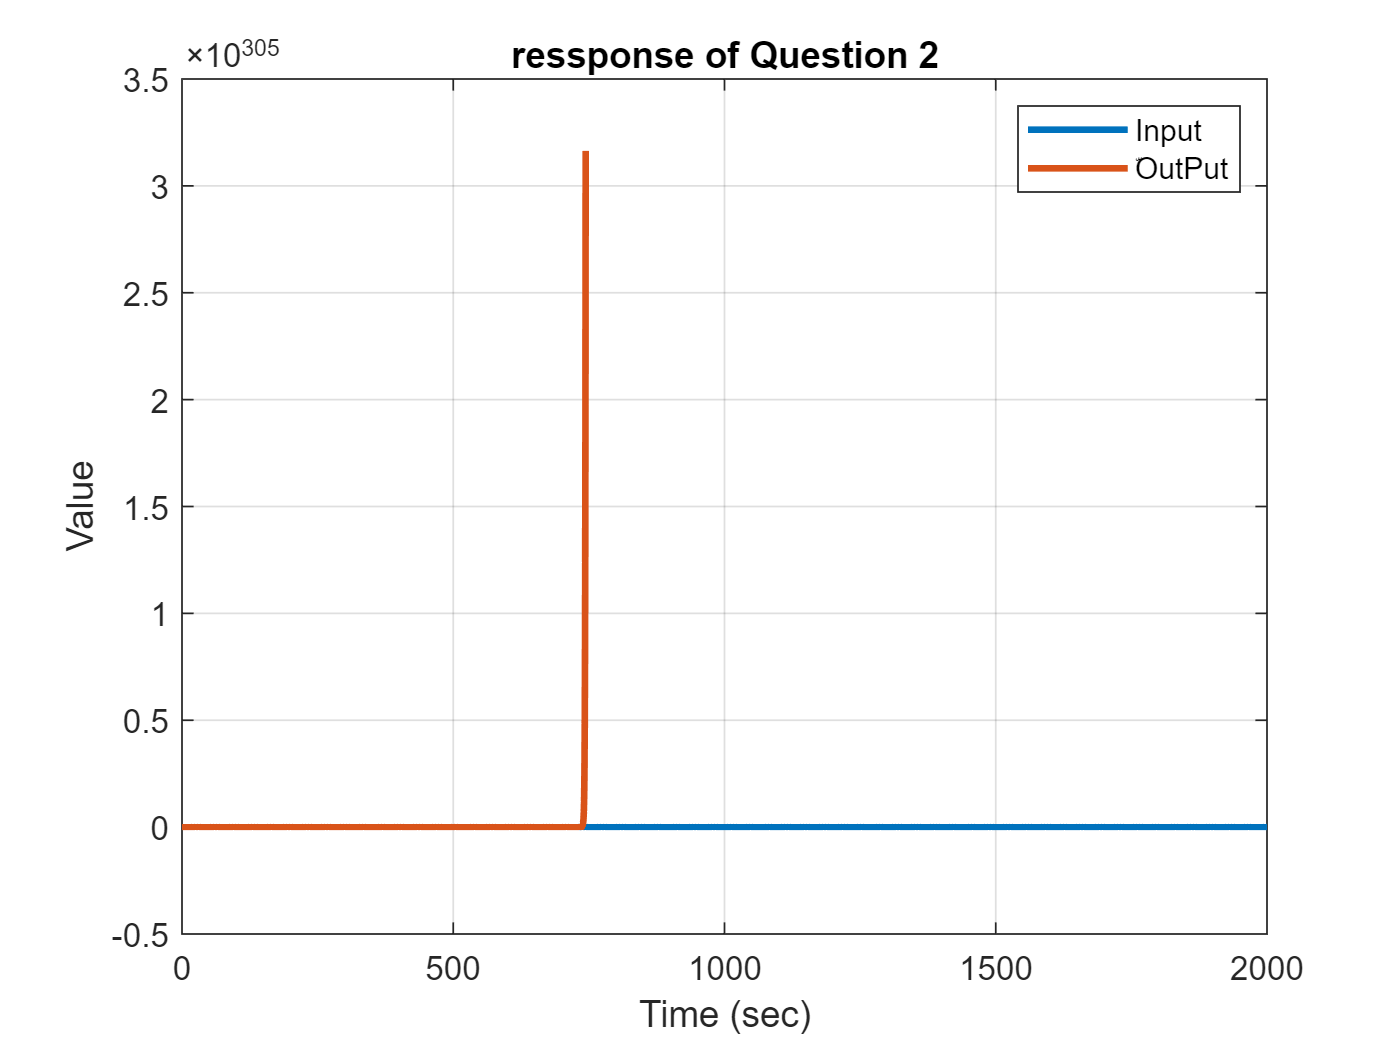

y = lsim(sys_discret  ,uc ,t)';
y_ref = lsim(sys_ref , uc , t) ;
plot(t,uc ,t , y ,'LineWidth',2) ;
xlabel('Time (sec)') ;
ylabel('Value') ;
title('ressponse of Question 2') ;
grid on
legend('Input' , 'ّOutPut') ;


n = numel(A)-1 ;
m = numel(B)-1 ;
N = numel(t) ;

Bplus  = 1;
Bminus = B;
d0 = n-m;

## MDPP STR (Direct)

A0 = [1 zeros(1,numel(A)-numel(Bplus)-1)];
Ac = conv(conv(Bplus,Am),A0);

A0Am = conv(A0 , Am) ;
Na0am = numel(A0Am)-1 ;
l = Na0am-d0 ; % deg(S)=deg(R)=l
Nv = 7 ;

Phi = [];
teta = 1*ones(Nv , 1);
S_vec = [];
R_vec = [];
P = 1e16*eye(Nv) ;
lambda = 1;

Nv_sys=6;
% theta=1*ones(Nv_sys , 1);

theta=repmat([-2.4831    1.4825   -0.1109 -0.0021   -0.0134    0.0335],6);

P_sys=1e1*eye(6);

% if we have zero cancellation: n = d0+L
% else n~= d0+L
u  = 0.1*ones(1,N) ;  % initial effort control
y  = 0.1*ones(1,N) ;  % initial output
uf = 0.1*ones(1,N) ;  % initial filtered effort control
yf = 0.1*ones(1,N) ;  % initial filtered output
ucf= 0.1*ones(1,N) ;  % initial filtered command signal

## main loop

% if we does not zero cancellation the for loop should start from "d0+L+1" iteration
% else we start from "n+1" iteration
for i = 4:N
    y(i) = [-(y(i-1:-1:i-n)),(u(i-(n-m):-1:i-n))]*[den_discret(2:end),num_discret]';

    %     U = -y(i-1:-1:i-3)  ;
    %     V = uc(i-1:-1:i-3)  ;
    %     Y = y(i)            ;

    phi(:,i) = [(y(i-1:-1:i-3)) , (u(i-1:-1:i-3))];
    K = P_sys*phi(:,i)*(1+phi(:,i)'*P_sys*phi(:,i))^(-1) ;
    P_sys = (eye(6) - K*phi(:,i)')*P_sys ;
    theta(:,i) = theta(:,i-1) + K*(y(i) - phi(:,i)'*theta(:,i-1));

    A=[1 -theta(1:3 ,end)'];
    B=theta(4:6,end)';

    if i>30
        U = uf(i-d0:-1:i-3)                 ;
        V = [yf(i-d0:-1:i-3) , -ucf(i-d0)]  ;
        Y = y(i)-y_ref(i)                   ;
        [teta , P] = RLS_1(U , V , Y , teta , P , Nv) ;

        R_h = teta(1:3)' ;
        S_h = teta(4:6)' ;
        t0   = teta(7)'   ;
        T=t0*A0;

        u(i)   = (-u (i-1:-1:i-2)*R_h(2:end)' + uc(i:-1:i-2)*T' - y(i:-1:i-2)*S_h')/R_h(1) ;
        yf(i)  = -yf (i-1:-1:i-Na0am) *A0Am(2:end)' + y (i:-1:i-2)*B' ;
        uf(i)  = -uf (i-1:-1:i-Na0am) *A0Am(2:end)' + u (i:-1:i-2)*B' ;
        ucf(i) = -ucf(i-1:-1:i-Na0am+2) *Am(2:end)' + uc(i:-1:i-2)*B' ;
    end
end

## plot results

input and output

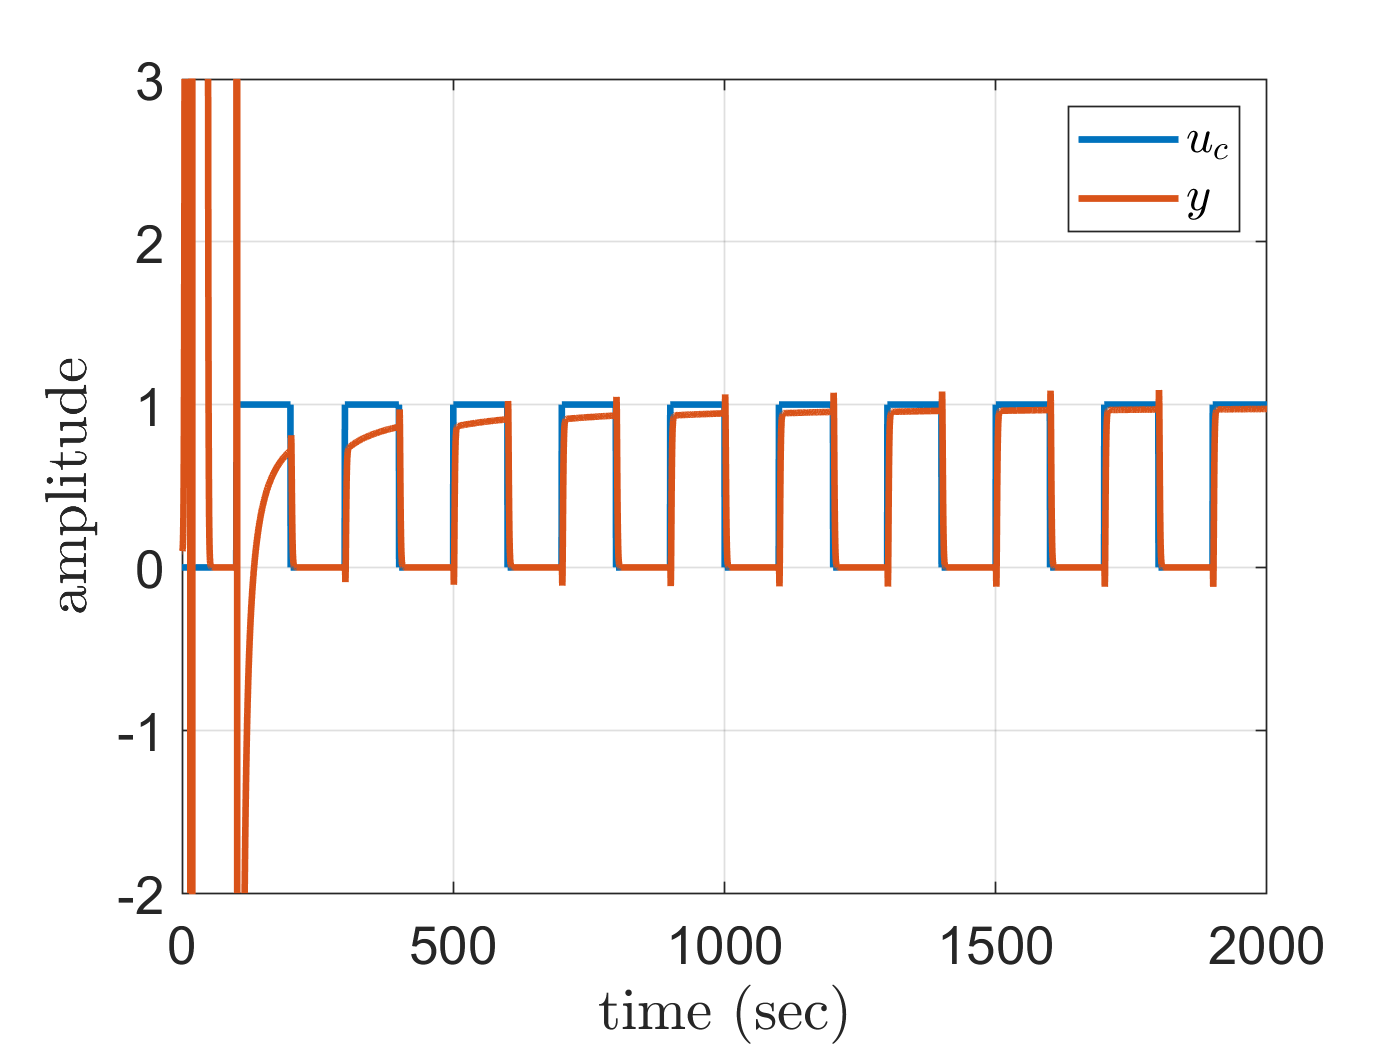

plot(t,uc,t,y , 'LineWidth' , 2) ;
xlabel('time (sec)','Interpreter','latex') ;
ylabel('amplitude','Interpreter','latex') ;
legend('$$u_c$$','$$y$$','Interpreter','latex','Location','northeast')
set(gca,'FontSize',16)
axis([0 tfinal -2 3])
grid on
print(gcf,'y v.s. refrence signal.png','-dpng','-r500');

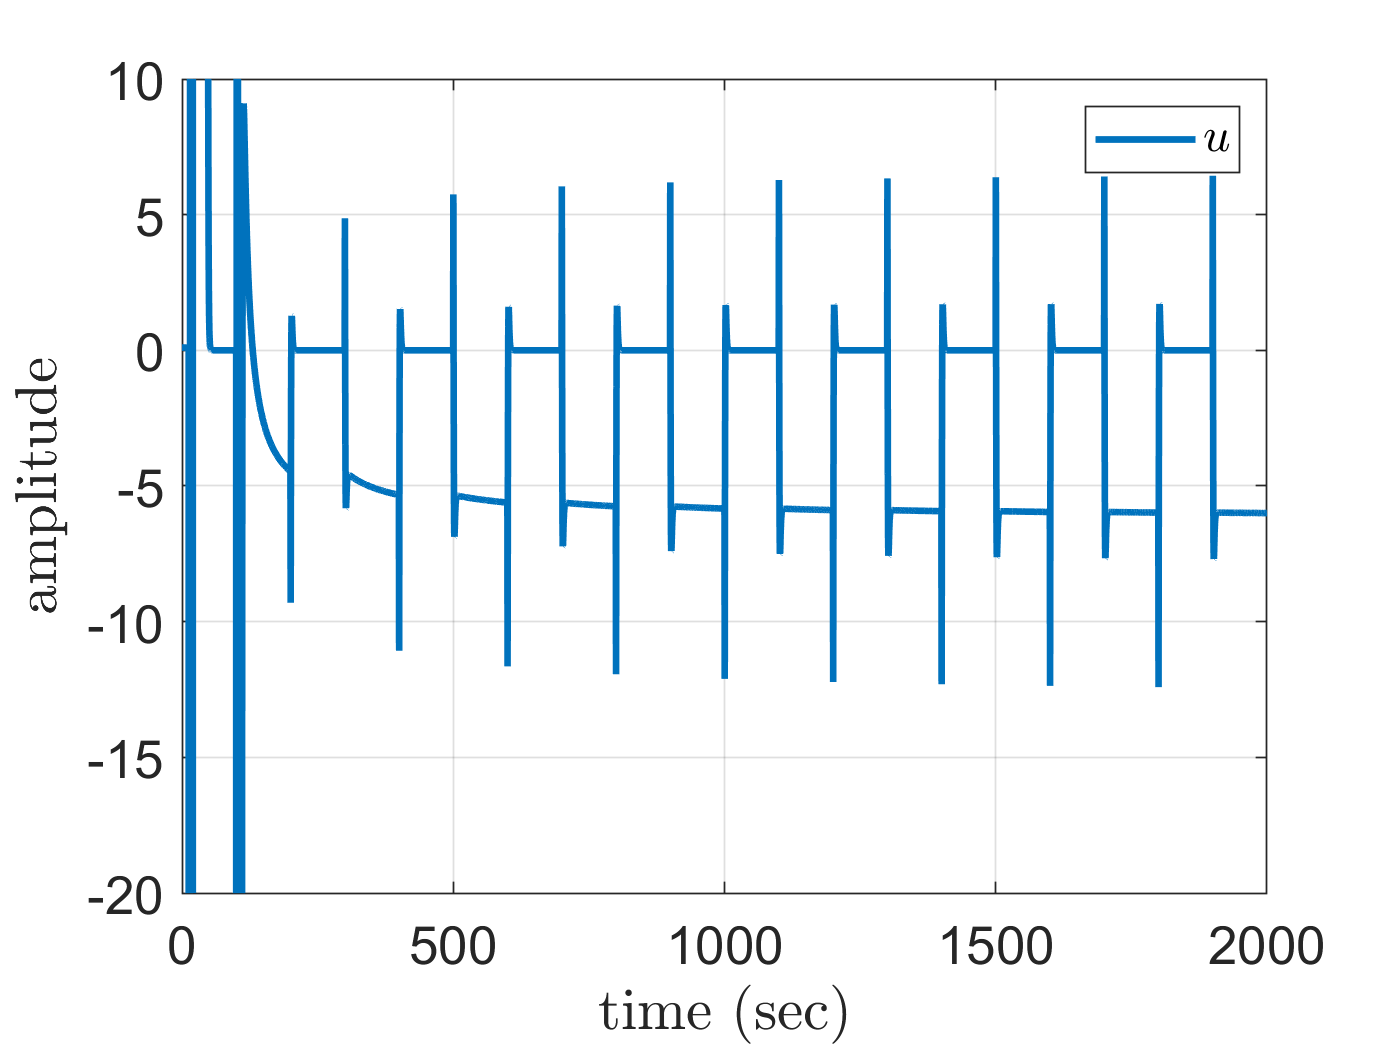


plot(t , u, 'LineWidth' , 2) ;
xlabel('time (sec)','Interpreter','latex') ;
ylabel('amplitude','Interpreter','latex') ;
legend('$$u$$','Interpreter','latex','Location','northeast')
set(gca,'FontSize',16)
 axis([0 tfinal -20 10])
grid on
print(gcf,'control signal.png','-dpng','-r500');

function [teta , P] = RLS_1(U , V ,Y, teta , P , Nv)
U = U(:)' ;
V = V(:)' ;
phi = [U , V]' ;
K = P*phi*(1+phi'*P*phi)^(-1) ;
P = (eye(Nv) - K*phi')*P ;
teta = teta + K*(Y - phi'*teta ) ;
end